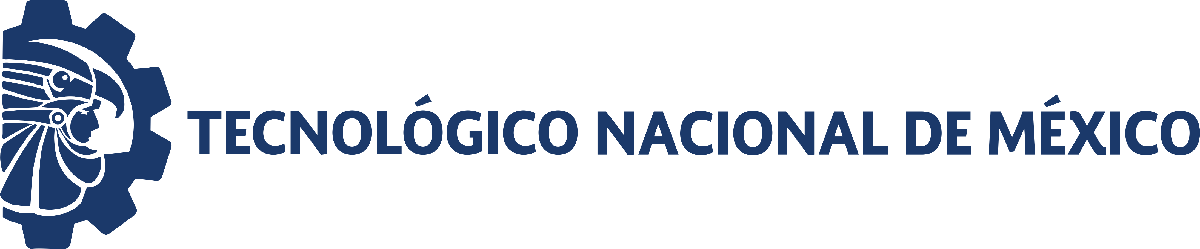                                 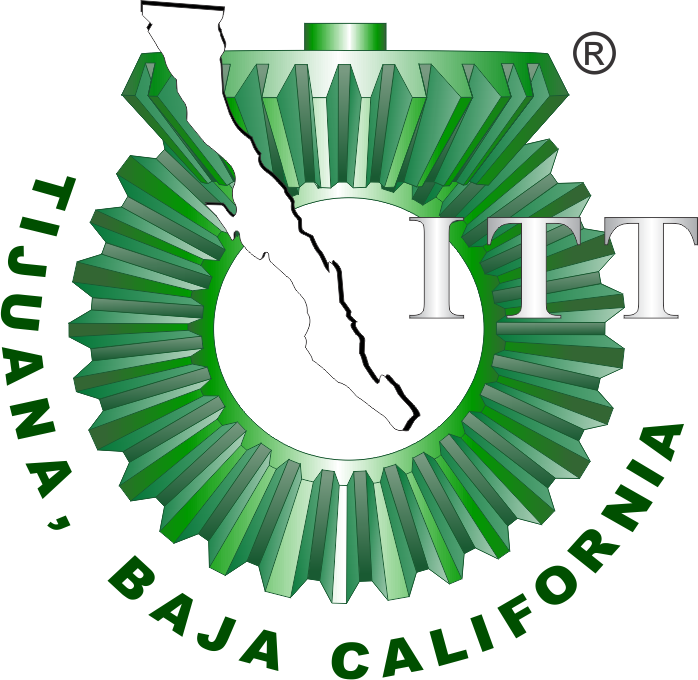

# Práctica 3: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

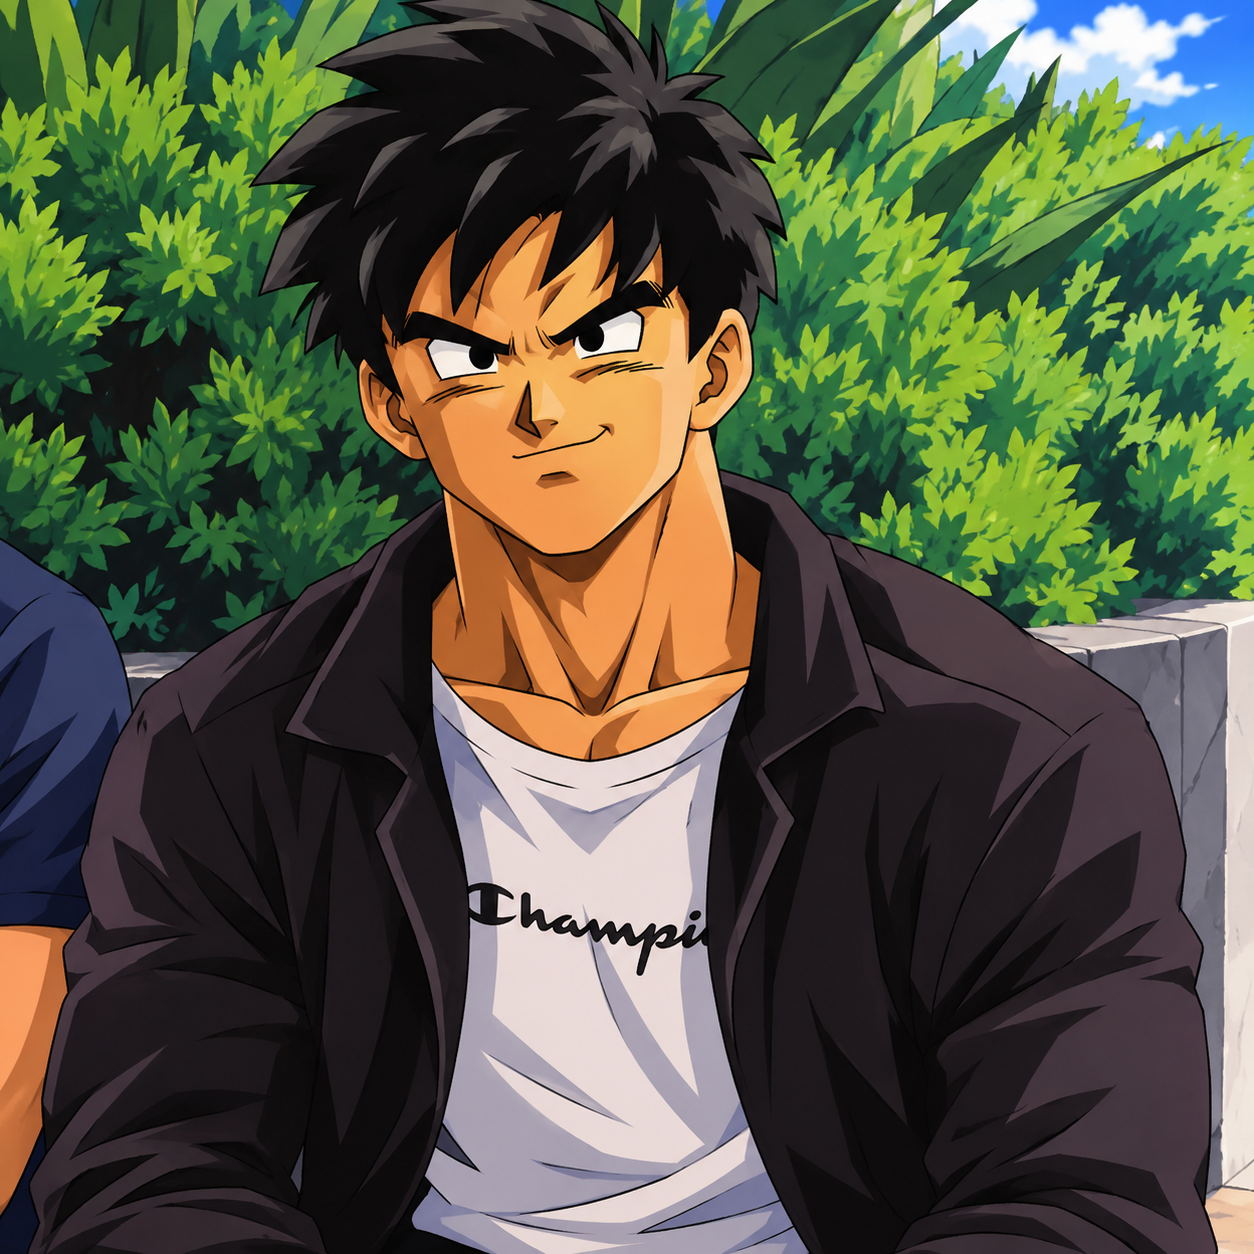

Nombre del alumno: Morales Diaz Ramon Ivan 

Número de control: 24210589

Correo institucional: l24210589**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
modelo = 'Sistemas';
open_system(modelo)
parameters.StopTime = '10';
parameters.Solver   = 'ode15s';
parameters.MaxStep  = '1e-3';
x = sim('Sistemas', parameters);

## Caso con tratamiento

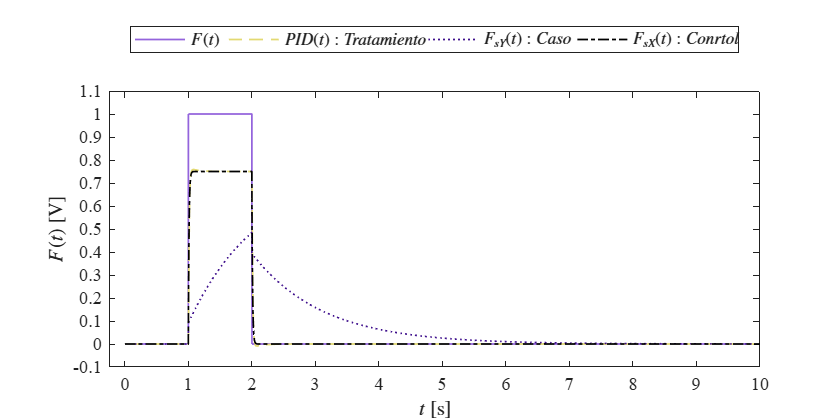

plotsignals(x.t, x.F, x.PID, x.Fsy, x.Fsx, 'CCT')

## Modelo EDOs

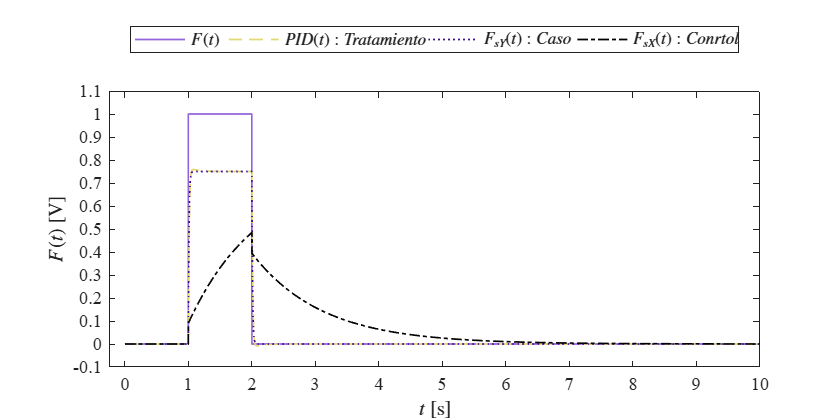

dt = 1e-3;
t = (0:dt:10);
F = zeros(length(t),1); F(1/dt:2/dt) = 1;
PID = interp1(x.t, x.PID, t, 'previous');

par_control = [0.25,10e-6,100e-6,100];
par_caso = [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control,F,t);
Fs_caso = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,PID,Fs_control,Fs_caso,'EDOsys')



function Fs = musculoesqueletico(par,F,t)
    alpha = par(1); Cs = par(2); Cp = par(3); R = par(4); dt = t(2);
    n = round(t(end)/dt);
    x = zeros(length(t),1); x(1) = 0;
    Fs = zeros(length(t),1); Fs(1) = 0;
    for i = 1:n
        x(i+1) = x(i) +((F(i)-x(i))/(R*(Cp+Cs)))*dt; %EDO
        Fs(i+1) = Cs*F(i)/(Cp+Cs) + (1 - alpha - Cs/(Cp+Cs))*x(i); %Funcion
    end
end


function plotsignals(t,x1,x2,x3,x4,signal)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = ([149, 100, 221])/256;
clr2 = ([228, 218, 114])/256;
clr3 = ([62, 15, 141])/256;
clr4 = ([0, 0, 0])/256;
order = [clr1;clr2;clr3;clr4]; colororder(order)
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$F(t)$ [V]','Interpreter','latex')
xlim([-0.25 10]); xticks(0:1:10)

if signal == "CCT"
    plot(t,x1,'-',t,x2,'--',t,x3,':',t,x4,'-.','LineWidth',1)
    L = legend('$F(t)$','$PID(t): Tratamiento $','$F_{sY}(t): Caso$','$F_{sX}(t): Conrtol$');

    elseif signal == "EDOsys"
           plot(t,x1,'-',t,x2,'--',t,x3,':',t,x4,'-.','LineWidth',1)
           L = legend('$F(t)$','$PID(t): Tratamiento $','$F_{sY}(t): Caso$','$F_{sX}(t): Conrtol$');

    end
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end